# ODE Examples

Let us consider the earth and sun, which are of scaled masses $\mu_{1\;} =0\ldotp 012277471$ and $\mu_2 =1-\mu_1 \;$.  The moon, of which the mass is negligible is moving in the same plane. The motion is governed by the following equations.

                                                                        
$$u_1''=u_1+2u_2'-{\mu_2} \frac{u_1+\mu_1}{D_1} - \mu \frac{u_1-\mu_2}{D_2}\\
u_2''=u_2-2u_1'-\mu_2 \frac{u_2}{D_1}-\mu_1 \frac{u_2}{D_2}\\
D_1=((u_1+\mu_1)^2+u_2^2)^{3/2}\\
D_2=(u_1-\mu_2)^2+u_2^2)^{3/2}
$$


Starting with the following initial conditions


$$u_1(0)=0.994,\quad u_1'(0)=0,\\
u_2(0)=0, \quad u'_2(0)=-2.00158510637908,$$


the solution is periodic with period $<17\ldotp 1$. 

y0 = [.994; 0; 0; -2.00158510637908252240537862224];
tspan = [0 17.1];

## RK4 method

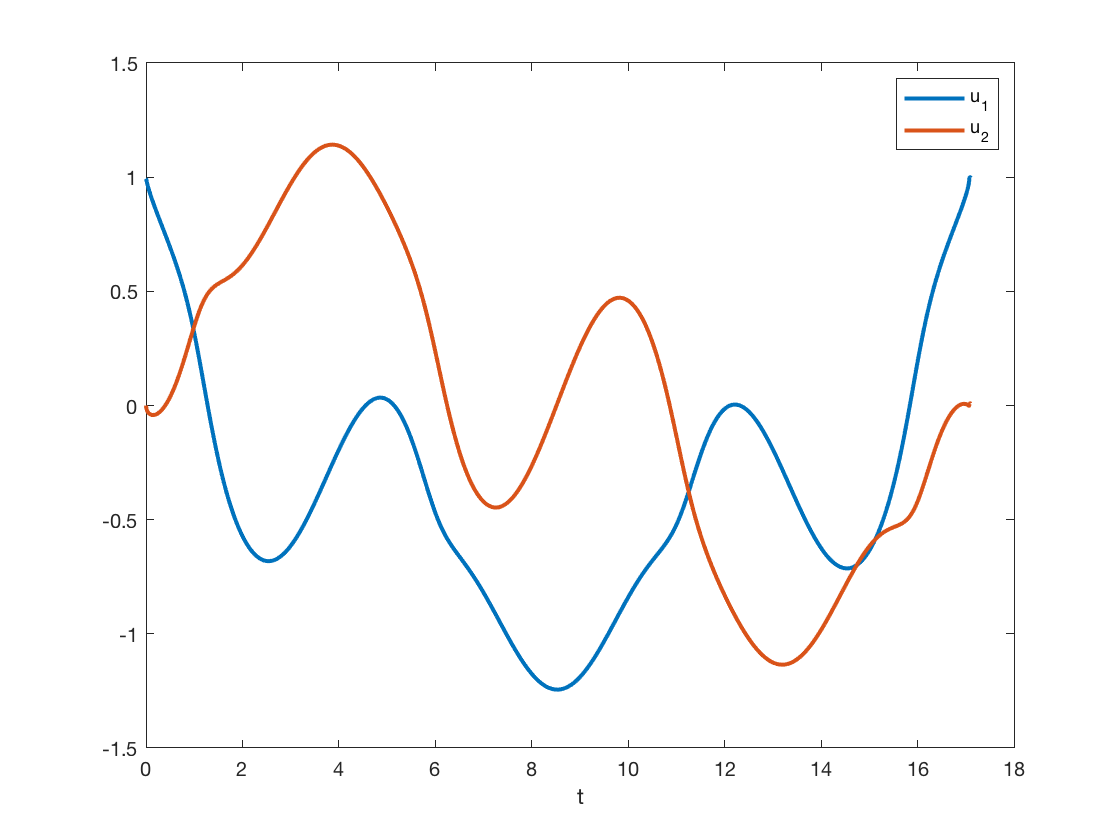

n_steps=10000;

dt = (tspan(2)-tspan(1))/n_steps;

[t_grid, u] = rk4(@func,tspan,y0, dt);

figure(1)
plot(t_grid, u(1,:), t_grid, u(3,:), 'LineWidth', 2)
hold on
% plot(t_grid, zeros(size(t_grid)), 'b*')
hold off
xlabel('t')
legend('u_1','u_2')

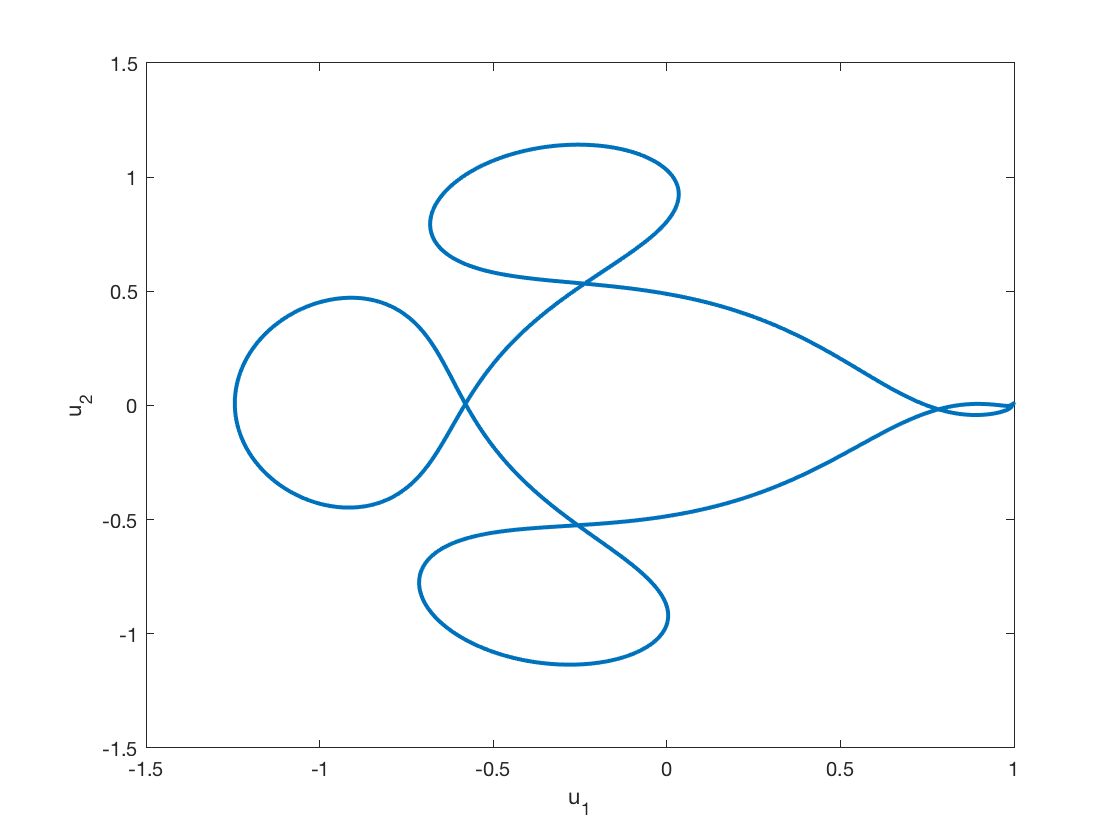


figure(2)
plot(u(1,:),u(3,:), 'LineWidth', 2)
xlabel('u_1')
ylabel('u_2')      

## RK45 Method

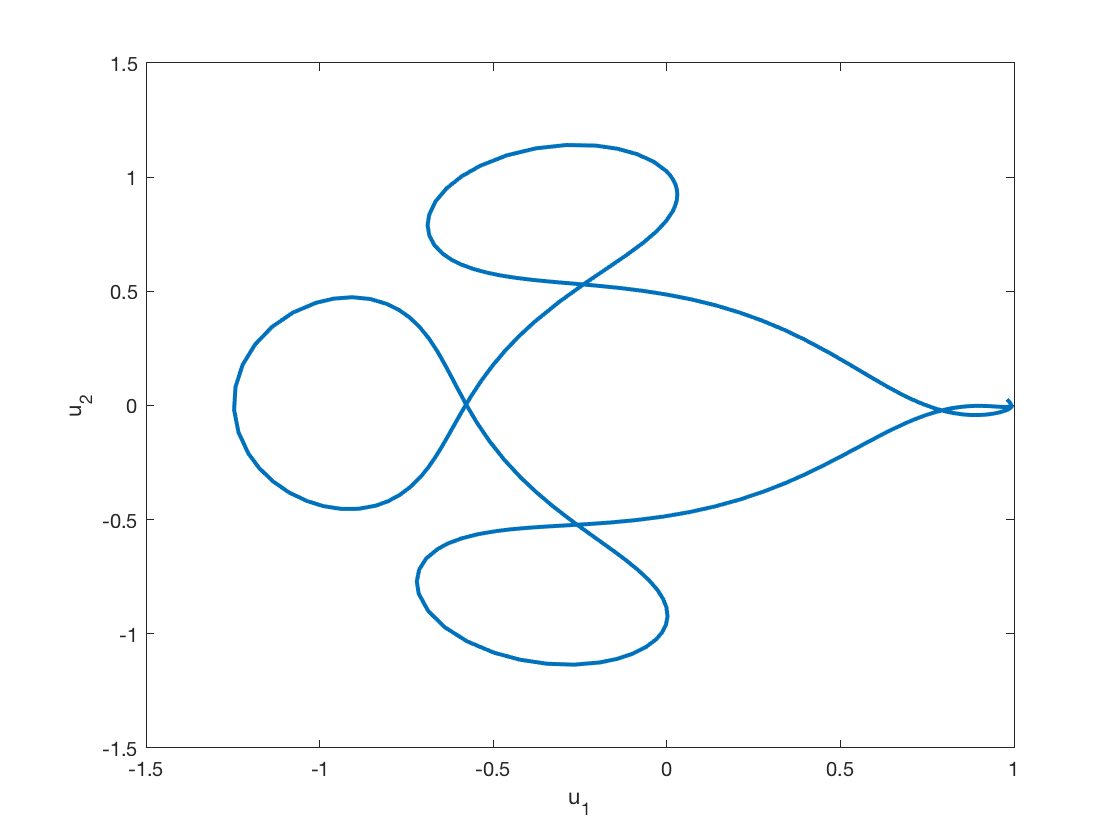

options=odeset('RelTol', 1e-3);
[tout,yout] = ode45(@func,tspan,y0, options); %func(t, y)
yout = yout';

figure(1)
plot(yout(1,:),yout(3,:), 'LineWidth', 2)
xlabel('u_1')
ylabel('u_2')

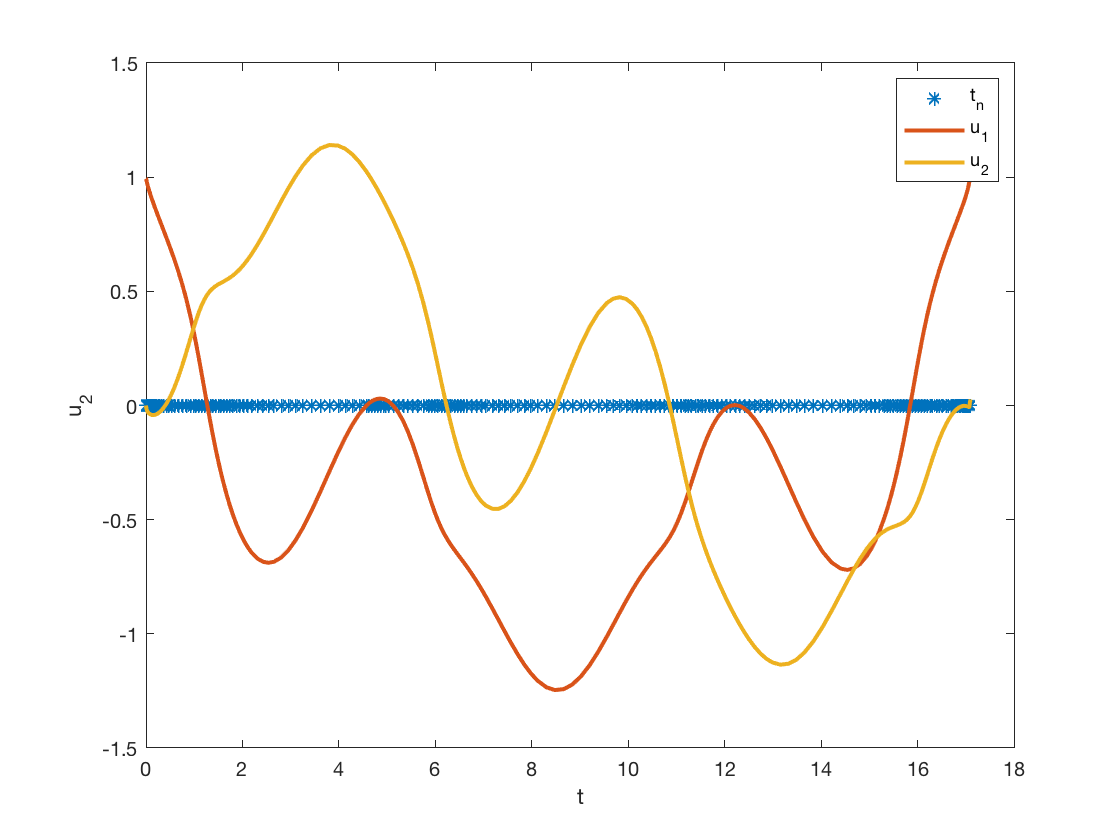


figure(2)
plot(tout, zeros(size(tout)), '*');
hold on
plot(tout, yout(1,:), 'LineWidth', 2)
xlabel('t')
ylabel('u_1')
plot(tout, yout(3,:), 'LineWidth', 2)
xlabel('t')
ylabel('u_2')
hold off
legend('t_n', 'u_1', 'u_2')

step_sizes=tout(2:end)-tout(1:end-1);
max_step=max(step_sizes);
min_step=min(step_sizes);
    
disp(['Total number time steps: ', num2str(length(tout))]);

Total number time steps: 309


disp(['The max step size: ', num2str(max_step)])

The max step size: 0.18915


disp(['The min step size: ', num2str(min_step)])

The min step size: 1.5921e-07


# Stiff Example

Consider the following simple ODE

                                                    
$$u'=-1000(u-\cos(t))-\sin(t), \\
u(0)=1.
$$


It has the smooth solution

                                                        
$$u(t)=\cos(t).$$


u0=1;
f=@(t, u) -1000*(u-cos(t))-sin(t);
u_exact=@(t) cos(t);
tspan = [0, pi/2];

## RK4 Method

n_steps=1000;

dt = (tspan(2)-tspan(1))/n_steps;

[t_grid, u] = rk4(f,tspan,u0, dt);

disp(['error=', num2str(abs(u(end)-u_exact(tspan(2))))])

error=2.1284e-10


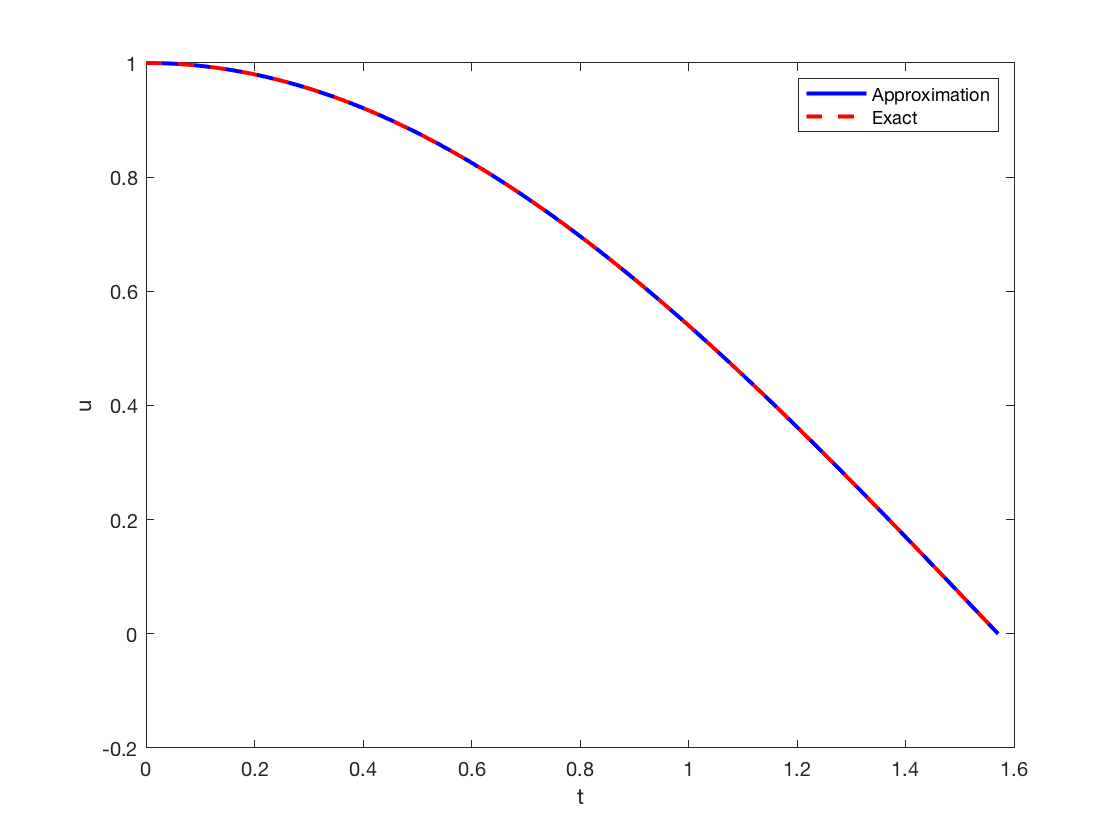


figure(1)
plot(t_grid, u, 'b-', 'LineWidth', 2)
hold on
plot(t_grid, u_exact(t_grid), 'r--', 'LineWidth',2)
hold off
legend('Approximation', 'Exact')
xlabel('t'); ylabel('u')

## ode45 Solver (RK4+RK5)

options=odeset('RelTol', 1e-10);
[t_grid, u]=ode45(f, tspan, u0, options);

disp(['error=', num2str(abs(u(end)-u_exact(tspan(2))))])

error=7.1771e-08


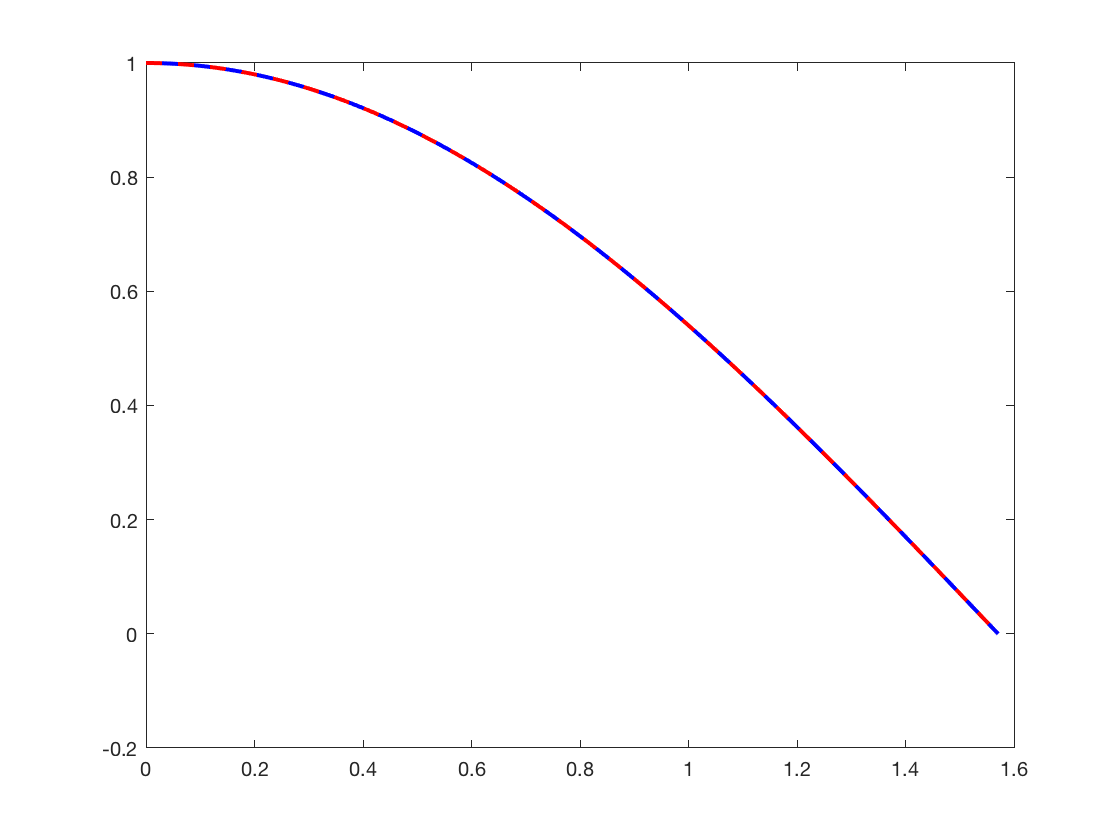


figure
plot(t_grid, u, 'b-', 'LineWidth', 2);
hold on
% plot(t_grid, zeros(size(t_grid)), 'b*');
plot(t_grid, u_exact(t_grid), 'r--', 'LineWidth', 2);
hold off

step_sizes=t_grid(2:end)-t_grid(1:end-1);
max_step=max(step_sizes);
min_step=min(step_sizes);
    
disp(['Total number time steps: ', num2str(length(t_grid))]);

Total number time steps: 2261


disp(['The max step size: ', num2str(max_step)])

The max step size: 0.00082446


disp(['The min step size: ', num2str(min_step)])

The min step size: 0.00049087


## ode113 solver (Adams-Bashforth + Adams-Moulton)

options=odeset('RelTol', 1e-4);
[t_grid, u]=ode113(f, tspan, u0, options);

disp(['error=', num2str(abs(u(end)-u_exact(tspan(2))))])

error=2.3051e-07


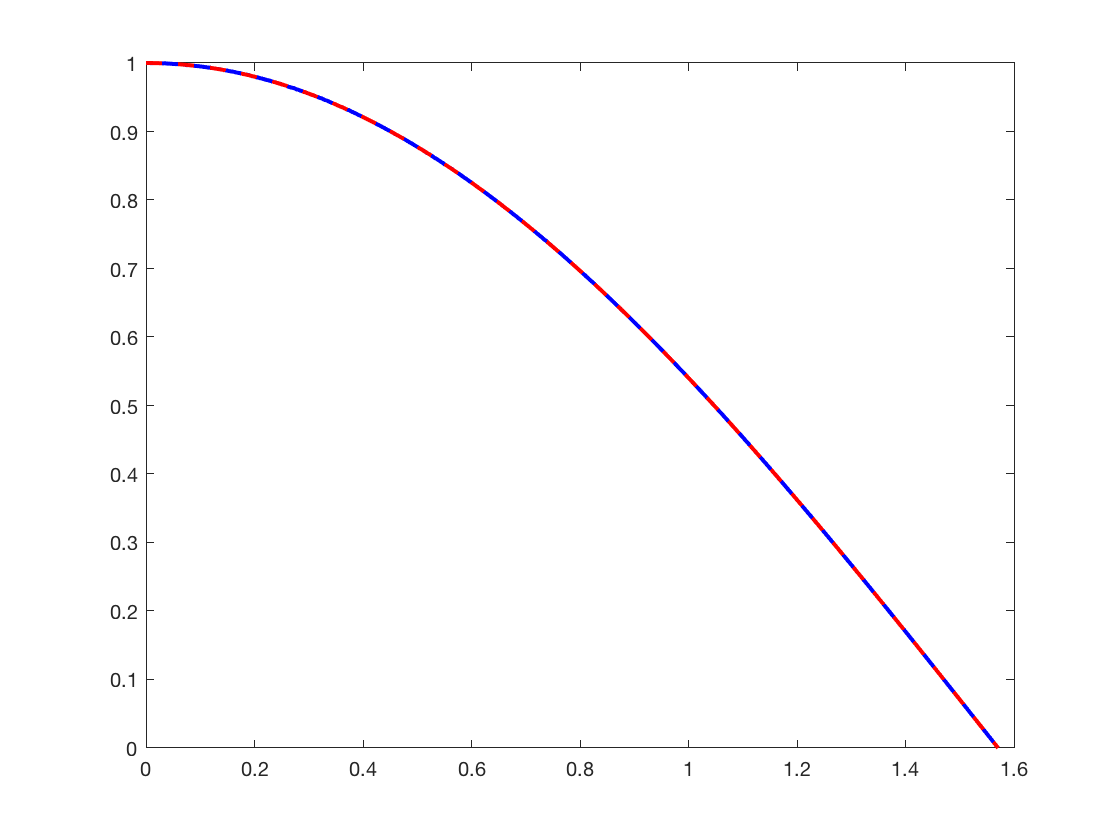


figure;
plot(t_grid, u, 'b-', 'LineWidth', 2);
hold on
% plot(t_grid, zeros(size(t_grid)), 'b*');
plot(t_grid, u_exact(t_grid), 'r--', 'LineWidth', 2);
hold off

step_sizes=t_grid(2:end)-t_grid(1:end-1);
max_step=max(step_sizes);
min_step=min(step_sizes);
    
disp(['Total number time steps: ', num2str(length(t_grid))]);

Total number time steps: 999


disp(['The max step size: ', num2str(max_step)])

The max step size: 0.0069806


disp(['The min step size: ', num2str(min_step)])

The min step size: 0.00043629


## Solver for stiff problems: ode15s (based on numerical differential formulas such as the BDF ones)

options=odeset('RelTol', 1e-7);
[t_grid, u]=ode15s(f, tspan, u0, options);

disp(['error=', num2str(abs(u(end)-u_exact(tspan(2))))])

error=4.9458e-10


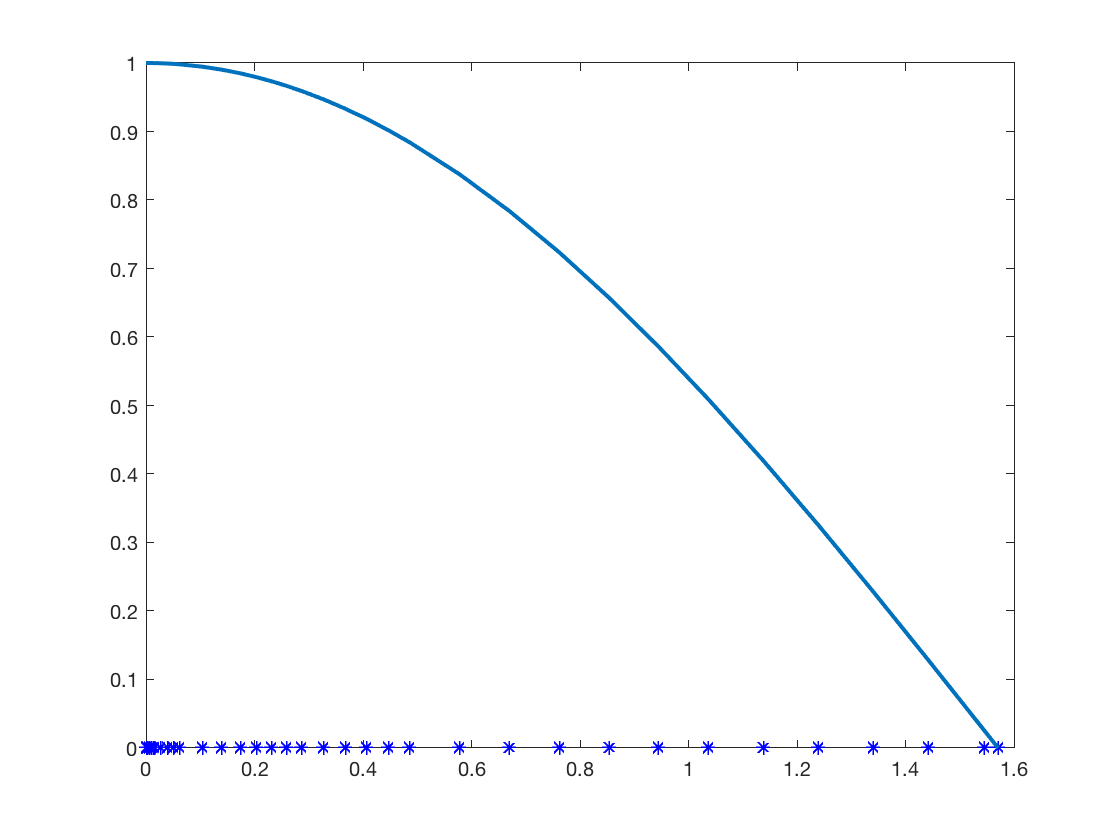

figure
plot(t_grid, zeros(size(t_grid)), 'b*')
hold on
plot(t_grid, u, 'LineWidth', 2);
hold off

step_sizes=t_grid(2:end)-t_grid(1:end-1);
max_step=max(step_sizes);
min_step=min(step_sizes);
    
disp(['Total number time steps: ', num2str(length(t_grid))]);

Total number time steps: 36


disp(['The max step size: ', num2str(max_step)])

The max step size: 0.10154


disp(['The min step size: ', num2str(min_step)])

The min step size: 0.0011314


# Swinging Pendulum

Consider the following linearized model for a swinging pendulum,  

$\theta''(t)+a\theta(t)+b\theta'(t)=0, \quad a\geq 0, b\geq 0$,

which is valid for small angle $\theta$. 

If we set


$$u_1=\theta,\quad u_2=\theta'(t),$$


we have the following first-order system,


$$u_1'=u_2,\\
u_2'=-au_1-bu_2.$$


In the matrix form $\mathbf{u}'=A\mathbf{u}$, where$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-a & -b
\end{array}\right\rbrack$.

The eigenvalues are $\lambda=\frac12 \left(-b\pm \sqrt{b^2-4a}\right)$. Note that

- if there is no damping, i.e., $b=0$, then $\lambda=\pm \sqrt{-a}$, which are pure imaginary.

- if $b>0$, the eigenvalues lie in the left half-plane. 

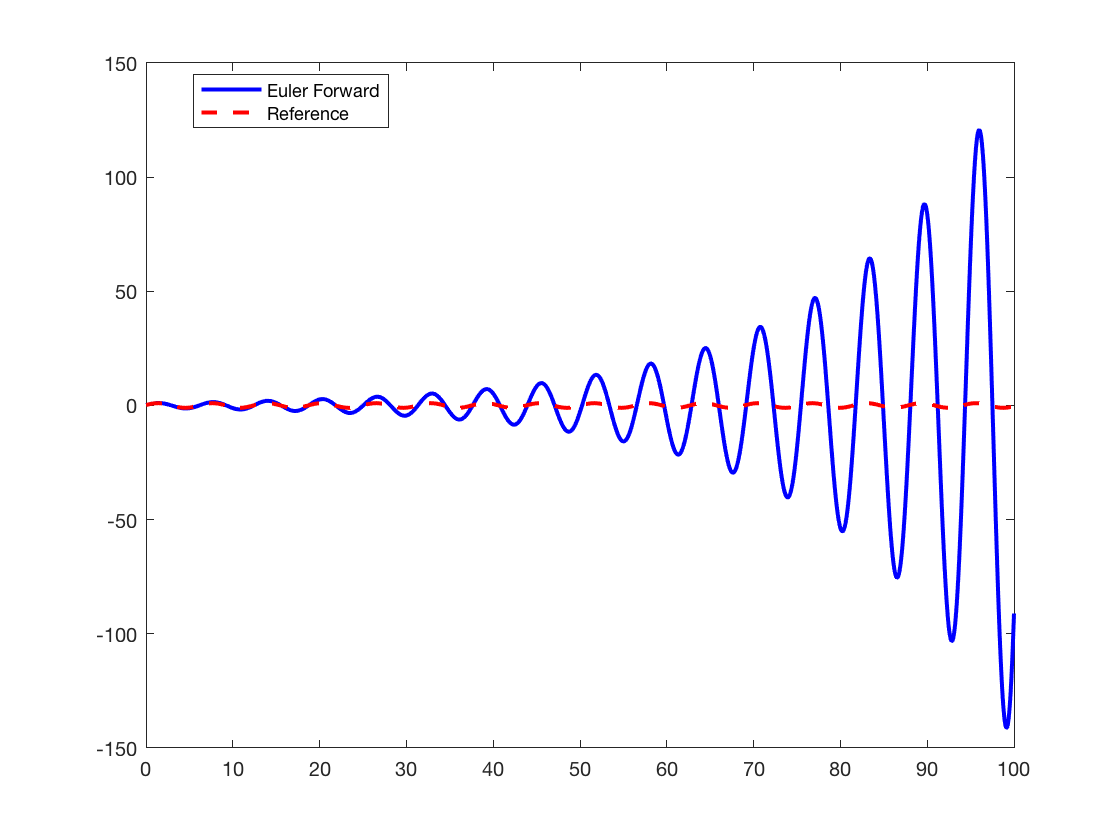

u0=[0.2, 1];
b=0; a=1;
f=@(t, u) [u(2); -a*u(1)-b*u(2)];

tspan = [0, 100];
dt=1e-1;

[t_rk45, u_rk45]=ode45(f, tspan, u0);

%Euler method
[t_grid, u]=Euler_Forward(f, tspan, u0, dt);
plot(t_grid, u(1,:), 'b-', 'LineWidth', 2, 'DisplayName', 'Euler Forward')
hold on
plot(t_rk45, u_rk45(:,1), 'r--', 'LineWidth', 2, 'DisplayName', 'Reference');
hold off
legend('Location', 'best')

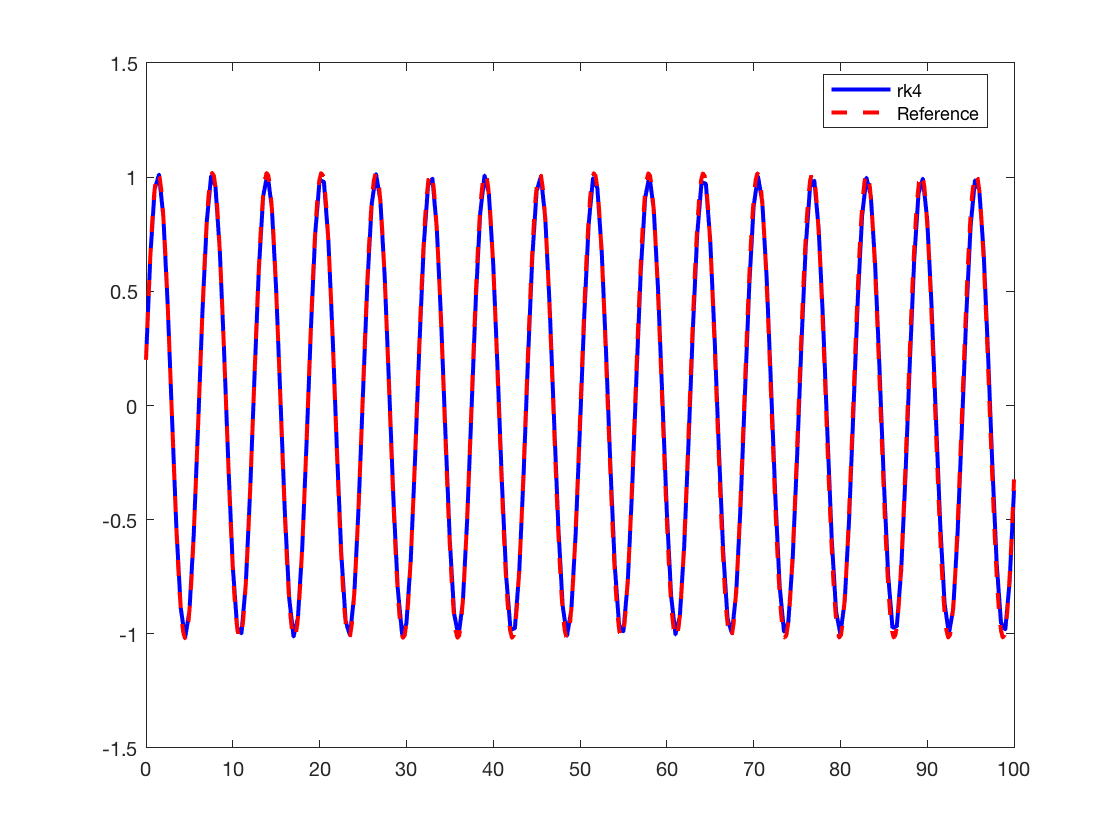

%RK4 method
dt=5e-1;
[t_rk4, u_rk4]=rk4(f, tspan, u0, dt);
plot(t_rk4, u_rk4(1,:), 'b-', 'LineWidth', 2, 'DisplayName', 'rk4')
hold on
plot(t_rk45, u_rk45(:,1), 'r--', 'LineWidth', 2, 'DisplayName', 'Reference');
hold off
legend('Location', 'best')

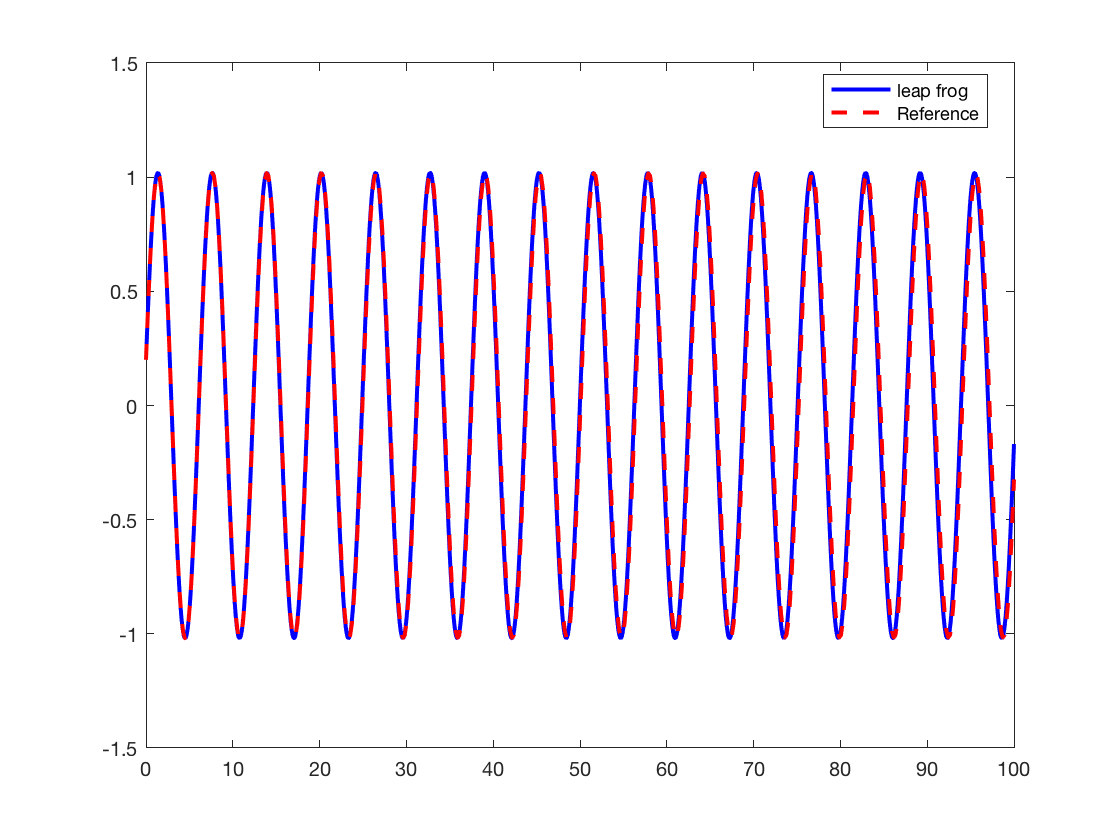

%Midpoint method
dt=1e-1;
[t, u]=leap_frog(f, tspan, u0, dt);
plot(t, u(1,:), 'b-', 'LineWidth', 2, 'DisplayName', 'leap frog')
hold on
plot(t_rk45, u_rk45(:,1), 'r--', 'LineWidth', 2, 'DisplayName', 'Reference');
hold off
legend('Location', 'best')